# Lab 5

## Es 1

load("test_functions2.mat", '-mat')

alpha0 = 5;
c1 = 1e-4;
rho = 0.8;
btmax = 50;
[xk, fk, gradfk_norm, k, xseq, eigs] = newton(x0, f2, gradf2, Hessf2, kmax, tolgrad)

xk =     1.0000
    1.0000


fk = 7.8886e-29

gradfk_norm = 7.4607e-14

k = 5

xseq =    -5.0000   -4.9990    0.9988    0.9988    1.0000    1.0000
   -5.0000   24.9900  -34.9760    0.9976    1.0000    1.0000


eigs = 1.0e+04 *

    0.0075    0.0000    0.0189    0.0000    0.0000    0.0000
    3.2127    2.0194    1.5200    0.1000    0.1002    0.1002


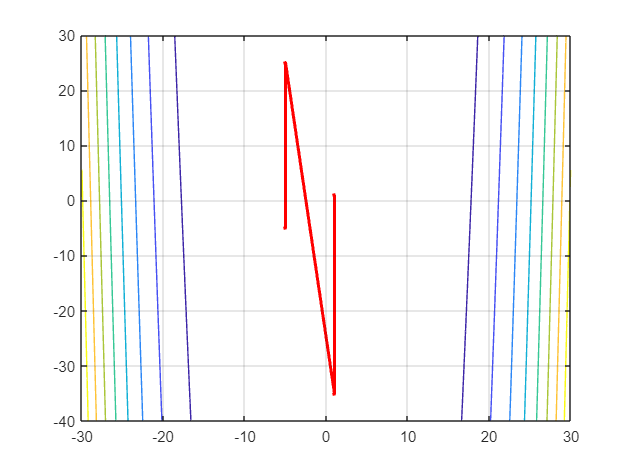

x = linspace(-30, 30, 200);
y = linspace(-40, 30, 200);
[X,Y] = meshgrid(x,y);
% Z = f3(x, y);
Z = 100*(Y-X.^2).^2 + (1-X).^2;
contour(X, Y, Z)
% surf(X,Y,Z)
grid on;
hold on;
h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 2, 'markersize', 2);

hold off